**AmirKabir University of Technology (Tehran Polytechnic)**

**Multi-Variable Control Systems - Assignment 02**                  **Mohammad Azimi - 402123100**

# Q1-

**Note: First Run the corresponing **`.m`** file to generate all the required variables for this script.**

## System Description

Let's break down each state of the linear UAV system:

- **Roll Angle Rate (x1):**

This state represents the change rate of the roll angle. Roll angle is the angle of rotation about the longitudinal axis of the aircraft, which is the axis running from the nose to the tail. The roll angle rate describes how quickly the aircraft is rotating around this axis.

- **Pitch Angle Rate (x2):**

Similar to roll angle rate, pitch angle rate represents the change rate of the pitch angle. Pitch angle is the angle of rotation about the lateral axis of the aircraft, which is the axis running from wingtip to wingtip. The pitch angle rate describes how quickly the aircraft is rotating around this axis.

- **Yaw Angle Rate (x3):**

Yaw angle rate represents the change rate of the yaw angle. Yaw angle is the angle of rotation about the vertical axis of the aircraft, which is the axis running from top to bottom through the center of the aircraft. The yaw angle rate describes how quickly the aircraft is rotating around this axis.

- **Forward Velocity along Body X (x4):**

This state represents the velocity component of the UAV in the forward direction along its body frame's x-axis. It indicates how fast the UAV is moving in the direction it is facing.

- **Vertical Velocity along Body Z (x5):**

Similar to forward velocity, this state represents the velocity component of the UAV in the upward direction along its body frame's z-axis. It indicates how fast the UAV is ascending or descending vertically.

- **UAV Altitude (x6):**

This state represents the altitude of the UAV, which is the vertical distance between the UAV and the ground or a reference point. It indicates how high the UAV is flying above the ground or sea level.

- **Roll Angle (x7):**

Roll angle represents the angle of rotation about the longitudinal axis of the aircraft at a given moment. It describes the orientation of the UAV with respect to the horizon in terms of roll.

- **Yaw Angle (x8):**

Yaw angle represents the angle of rotation about the vertical axis of the aircraft at a given moment. It describes the orientation of the UAV with respect to the horizon in terms of yaw.

- **Pitch Angle (x9):**

Pitch angle represents the angle of rotation about the lateral axis of the aircraft at a given moment. It describes the orientation of the UAV with respect to the horizon in terms of pitch.

- **Lateral Velocity along Body Y (x10):**

This state represents the velocity component of the UAV in the sideways direction along its body frame's y-axis. It indicates how fast the UAV is moving sideways.

These states collectively describe the dynamics and kinematics of the UAV in its flight. The control inputs (u1, u2, u3) are used to manipulate these states and control the behavior of the UAV in flight.

Now let’s have glance at what the outputs of the system are supposed.

- **y1 (Output):**

This output is the same as the roll angle (x7). It represents the orientation of the UAV with respect to the horizon in terms of roll.

- **y2 (Output):**

This output is the same as the yaw angle (x8). It represents the orientation of the UAV with respect to the horizon in terms of yaw.

- **y3 (Output):**

This output is the same as the pitch angle (x9). It represents the orientation of the UAV with respect to the horizon in terms of pitch.

These outputs provide information about the orientation of the UAV in flight, which can be useful for monitoring and controlling its trajectory and stability. They directly reflect the corresponding states of the system, providing observable variables for analysis and feedback control.

The state equations of the system can be represented in matrix form as:


$$\dot{x} =Ax+Bu$$


where:

 $\dot{x}$ represents the derivative of the state vector  with respect to time.

$A$ is the state matrix, which describes how the states evolve over time,

 $B$ is the input matrix, which describes how the control inputs affect the system dynamics,

 $u$ represents the control input vector.

In this system:

- **State Matrix (A):**

The matrix  is a 10x10 matrix that defines the dynamics of the UAV system. Each element of this matrix represents the influence of one state on the rate of change of another state. For example, element  represents how state  influences the rate of change of state . In other words, the non-zero elements of this matrix indicate the interdependencies among different states of the system.

- **Input Matrix (B):**

The matrix  is a 10x3 matrix that defines how the control inputs affect the dynamics of the system. Each column corresponds to one control input, and each row corresponds to one state. For example, element  represents how control input  affects the rate of change of state .

The state equations encapsulate the dynamic behavior of the UAV system, describing how the system's states evolve over time in response to control inputs and external influences. These equations are fundamental for understanding and modeling the behavior of the UAV in various flight conditions and for designing control strategies to achieve desired performance objectives.

## Transfer functions and Char Equations

for o=1:numOutputs  
    for i=1:numInputs
        fprintf("Transfer Function for Output_%d/Input_%d}= \n", o,i)
        eval(simplify(G(o,i)))
        fprintf("-------------------------------------------------------------\n")
    end
end

Transfer Function for Output_1/Input_1}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_1/Input_2}= 


$$ans = \frac{5004822650000000\,s^{2}+19302723374480500\,s+15127711141163841536}{50000000000000\,s^{4}+288700000000000\,s^{3}+152235817000000000\,s^{2}+287013076421095000\,s-67941684155290}$$

-------------------------------------------------------------


Transfer Function for Output_1/Input_3}= 


$$ans = \frac{522965000000000\,s^{2}+1645331858110000\,s+1139700250389880000}{5000000000000\,s^{4}+28870000000000\,s^{3}+15223581700000000\,s^{2}+28701307642109500\,s-6794168415529}$$

-------------------------------------------------------------


Transfer Function for Output_2/Input_1}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_2/Input_2}= 


$$ans = \frac{10510500000000\,s^{3}+9019895885000\,s^{2}+6987883141168930\,s+5961033410832500}{s\,\left(5000000000000\,s^{4}+28870000000000\,s^{3}+15223581700000000\,s^{2}+28701307642109500\,s-6794168415529\right)}$$

-------------------------------------------------------------


Transfer Function for Output_2/Input_3}= 


$$ans = \frac{500500000000000\,s^{3}+1394019627000000\,s^{2}+6127122087086000\,s+4490753767500000}{s\,\left(5000000000000\,s^{4}+28870000000000\,s^{3}+15223581700000000\,s^{2}+28701307642109500\,s-6794168415529\right)}$$

-------------------------------------------------------------


Transfer Function for Output_3/Input_1}= 


$$ans = \frac{12384898975268864000000000000000\,s^{2}+12499381603696528850944000000000\,s+128819416980013647187148800000}{11258999068426240000000000000\,s^{4}+111953305545941964554240000000\,s^{3}+110564533915333716303778152448000\,s^{2}+1416053177597400551150269235200\,s+29318635790759157485377945600}$$

-------------------------------------------------------------


Transfer Function for Output_3/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_3/Input_3}= 


ans = 0

-------------------------------------------------------------


Eigenvalues of matrix `A` are obtained as the following:

eig_A

eig_A =             0 +          0i
            0 +          0i
      -1.9421 +     55.078i
      -1.9421 -     55.078i
      -1.8901 +          0i
   0.00023669 +          0i
      -4.9653 +     98.971i
      -4.9653 -     98.971i
   -0.0064037 +   0.014972i
   -0.0064037 -   0.014972i


Thus, the characterisic equation of the open-loop system derives using `det(SI - A)`:

eval(det(s*eye(numStates) - A))

$$ans = \frac{\left(5000000000000\,s^{6}+28870000000000\,s^{5}+15223581700000000\,s^{4}+28701307642109500\,s^{3}-6794168415529\,s^{2}\right)\,\left(11258999068426240000000000000\,s^{4}+111953305545941964554240000000\,s^{3}+110564533915333716303778152448000\,s^{2}+1416053177597400551150269235200\,s+29318635790759157485377945600\right)}{56294995342131202682304162269958481379328}$$

Considering a **Negative Unity Feedback** (**-1** **feedback**) through all of the system states will lead into the following eigenvalues and charactristic equation.

eig_A_prime

eig_A_prime = 1.0e+03 *

  -0.7105 + 1.4075i
  -0.7105 - 1.4075i
  -0.0019 + 0.0484i
  -0.0019 - 0.0484i
  -0.0023 + 0.0000i
  -0.0002 + 0.0011i
  -0.0002 - 0.0011i
   0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i


And the characteristic equation for the colsed-loop system ( `det(SI - A + BK)` ) :

det(s*eye(numStates) - A_prime)

$$ans = s^{10}+\frac{100459576824243593173\,s^{9}}{70368744177664000}+\frac{494715049615599052173432128114412539707\,s^{8}}{198070406285660843983859875840000}+\frac{1671261387746435908539475589624138180330607949563376809\,s^{7}}{85070591730234615865843651857942052864000000000}+\frac{35215296445153175589466698151592863753141660748195518463367571887245573711\,s^{6}}{5986310706507378352962293074805895248510699696029696000000000000}+\frac{1221467275637943759203965206056108855132847394912259943677358507997950745071\,s^{5}}{74828883831342229412028663435073690606383746200371200000000000000}+\frac{5476612531227651190935161910339140494539919674921921274877738342324425508276742356717647\,s^{4}}{411376139330301510538742295639337626245683966408394965837152256000000000000000}+\frac{326289052139167417229170098179478532164228513324853545436047928021867878838995229857623489\,s^{3}}{20568806966515075526937114781966881312284198320419748291857612800000000000000000}+\frac{8133954669070315220599387538048803647730956631620293720737512729710600117158676552343611\,s^{2}}{51422017416287688817342786954917203280710495801049370729644032000000000000000000}-\frac{48616573357822695595965504366406763689666866016461946686148705532867289083\,s}{1496577676626844588240573268701473812127674924007424000000000000000000}$$

## How inputs would affect outputs

Based on the obtained transfer functions for the system, the following results are concluded:

Input 1 affects on output 3.

Input 2 affects on output 1 and 2.

Input 3 affects on output 1 and 2.

So, (**Note**: $G_{\textrm{ji}} :\textrm{Transfer}\;\textrm{Function}\;\textrm{respecting}\;Y_j \;\textrm{and}\;U_i \;i\ldotp e\ldotp \textrm{Output}\_j\;\textrm{and}\;\textrm{Input}\_i$)

- 
$$Y_1 =f\left(U_2 ,U_3 \right)=G_{12} U_2 +G_{13} U_3$$


- 
$$Y_2 =f\left(U_2 ,U_3 \right)=G_{22} U_2 +G_{23} U_3$$


- 
$$Y_3 =f\left(U_1 \right)=G_{32} U_1$$


The afrementioned results could be observed through `step` responses of the system in the following figure.

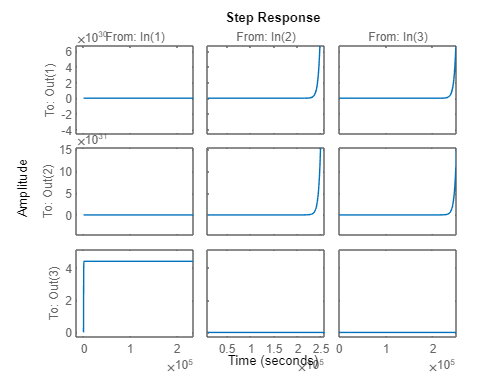

step(sys_ss)

open("Q1_UAV.slx")
out = sim("Q1_UAV.slx")

out =   Simulink.SimulationOutput:

                   tout: [462x1 double] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## System Simulation in SimuLink

We could implement the system in Simulink as follows:

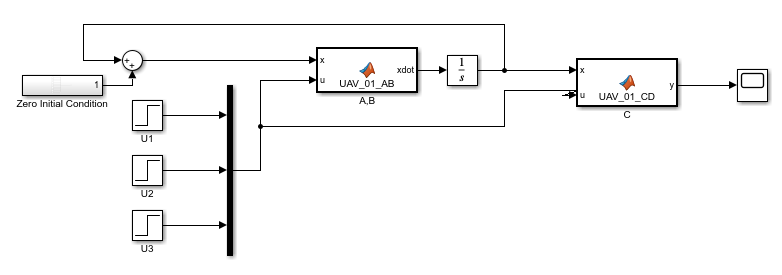

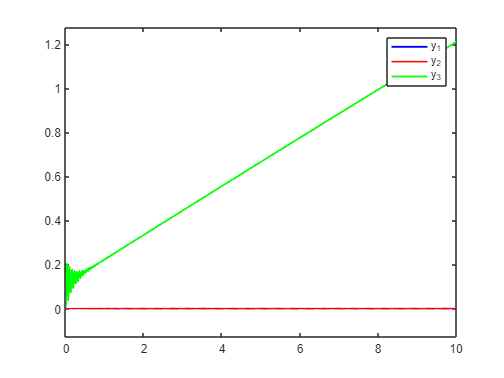

reshaped = reshape(out.y.Data , [3,size(out.y.Data,3)]);
figure
plot(out.tout, reshaped(1,:), Color="blue", LineWidth=1.5)
hold on
plot(out.tout, reshaped(2,:), Color="red", LineWidth=1.25)
plot(out.tout, reshaped(3,:), Color="green", LineWidth=1.5)
legend("y_1", "y_2", "y_3")

You can run the system under different inputs and initial conditions and study system behaviour.

## Controller Design

Since the eigenvalues of the system include instablity, we may want to desing a controller for the system in order to place its poles where we desire. The required condition for such design is that the Controllability Matrix of the system ( `U=ctrb(A,B)` ) is full rank. 

[rankU , numStates]

ans =      4    10


According the inequality $4\not= 10$, the system is not controllable and its poles can not be placed at any desired location. Considering the obtained poles for the system through unity feedback, unity feedback can not at least stabilize the system as it yet still remains one positive poles settled very close to the origin.

All these conditions means that although we can not place poles where we desire but some controllers may be able to place them where at least they are stable. To find such controller, we could take advantage of the command `lqr` and derive an optimal gain matrix `K`, all thanks to MATLAB. 

Let's try this out and see if it is able to place system poles where they are stable or not.

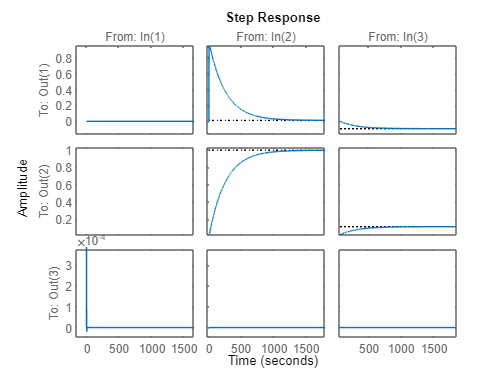

step(sys_lqr)

To conclude, we observed that a negative unity feedback can not stabilize the system. Hence, we used `lqr` MATALB command to find an optimal `K` for the feedback gain so that all poles are placed somewhere on the left-side of the s-plane i.e. their real part are negative, since rank of the controllability matrix is not full ( $\rho \left(U\right)=4<10$ ) and the system is not fully controllable.

## System Type

We know that the Type of a system equals to the number of poles at the origin. So let's recall the system poles which are the eigenvalues of the matrix `A.`

eig_A

eig_A =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -1.9421 +55.0782i
  -1.9421 -55.0782i
  -1.8901 + 0.0000i
   0.0002 + 0.0000i
  -4.9653 +98.9713i
  -4.9653 -98.9713i
  -0.0064 + 0.0150i
  -0.0064 - 0.0150i


Counting poles at the origin:

length(find(eig_A == 0))

ans = 2

So the maximum SystemType of which the system could behave is 2 and since the system is MIMO, Type of the system could vary for different transfer functions of the system due to the zero-pole cancelation throughout system realization.

To study each transfer function (**those that are nonzero**), we need to checkout their denominators.

for o=1:numOutputs  
    for i=1:numInputs
        fprintf("Transfer Function for Output_%d/Input_%d}= \n", o,i)
        eval(simplify(G(o,i)))
        fprintf("-------------------------------------------------------------\n")
    end
end

Transfer Function for Output_1/Input_1}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_1/Input_2}= 


$$ans = \frac{5004822650000000\,s^{2}+19302723374480500\,s+15127711141163841536}{50000000000000\,s^{4}+288700000000000\,s^{3}+152235817000000000\,s^{2}+287013076421095000\,s-67941684155290}$$

-------------------------------------------------------------


Transfer Function for Output_1/Input_3}= 


$$ans = \frac{522965000000000\,s^{2}+1645331858110000\,s+1139700250389880000}{5000000000000\,s^{4}+28870000000000\,s^{3}+15223581700000000\,s^{2}+28701307642109500\,s-6794168415529}$$

-------------------------------------------------------------


Transfer Function for Output_2/Input_1}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_2/Input_2}= 


$$ans = \frac{10510500000000\,s^{3}+9019895885000\,s^{2}+6987883141168930\,s+5961033410832500}{s\,\left(5000000000000\,s^{4}+28870000000000\,s^{3}+15223581700000000\,s^{2}+28701307642109500\,s-6794168415529\right)}$$

-------------------------------------------------------------


Transfer Function for Output_2/Input_3}= 


$$ans = \frac{500500000000000\,s^{3}+1394019627000000\,s^{2}+6127122087086000\,s+4490753767500000}{s\,\left(5000000000000\,s^{4}+28870000000000\,s^{3}+15223581700000000\,s^{2}+28701307642109500\,s-6794168415529\right)}$$

-------------------------------------------------------------


Transfer Function for Output_3/Input_1}= 


$$ans = \frac{12384898975268864000000000000000\,s^{2}+12499381603696528850944000000000\,s+128819416980013647187148800000}{11258999068426240000000000000\,s^{4}+111953305545941964554240000000\,s^{3}+110564533915333716303778152448000\,s^{2}+1416053177597400551150269235200\,s+29318635790759157485377945600}$$

-------------------------------------------------------------


Transfer Function for Output_3/Input_2}= 


ans = 0

-------------------------------------------------------------


Transfer Function for Output_3/Input_3}= 


ans = 0

-------------------------------------------------------------


It is seen that the system Type is never 2 as we had guessed in the first step. This is due to the zero-pole cancelation. Output 1 with respect to both Input 2 and 3 has the system Type 0 since there is no pole at the origin. Also output 3 has the Type 0 respecting Input 1. On the other hand, Output 2 has the system Type 1 under Input 2 and 3 due to its single pole at the origin.

## Singular Values Decomposition

We know that singular values of a matrix `A` are the square roots of the eigenvalues of $A^T A$ or ${\textrm{AA}}^T$. in MATLAB, one could use the command `svd` to obtain these values. Remeber that the correponding decomposition for matrix `A` is as follows:


$$A=\textrm{US}V^T$$


UU

UU =    -0.0000    0.0000    0.0003    0.0000    0.8827   -0.0697   -0.0000    0.0263    0.4640    0.0055
   -0.0000   -0.0036         0   -0.9998         0   -0.0000    0.0189    0.0000   -0.0000    0.0001
   -0.0000    0.0000    0.0011   -0.0000    0.1390    0.9834    0.0000   -0.0062   -0.1163   -0.0014
    0.0039   -0.0047   -0.0000   -0.0188    0.0000    0.0000   -0.9998   -0.0000   -0.0000    0.0021
    0.0127    0.9999    0.0000   -0.0037   -0.0000    0.0000   -0.0045   -0.0000    0.0000   -0.0004
   -0.9999    0.0127   -0.0000   -0.0001    0.0000   -0.0000   -0.0039   -0.0000   -0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.4490    0.1674   -0.0000    0.0452    0.8765    0.0104
   -0.0000    0.0000   -0.0004   -0.0000   -0.0021    0.0004   -0.0000    0.9986   -0.0526   -0.0006
    0.0000    0.0004    0.0000    0.0001   -0.0000   -0.0000    0.0021    0.0000   -0.0118    0.9999
   -0.0000   -0.0000    1.0000    0.0000   -0.0004   -0.0011   -0.0000    0.0004    0.

VV

VV =    -0.0000   -0.0000    0.0046   -0.0000   -0.9794    0.2021    0.0000   -0.0000   -0.0000   -0.0000
    0.0126    0.9999         0    0.0004   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
   -0.0000   -0.0000   -1.0000   -0.0000   -0.0046    0.0005   -0.0000    0.0039    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0458   -0.0000   -0.0000    0.9990    0.0000   -0.0000    0.0000
    0.0004   -0.0004   -0.0000    0.9990    0.0000    0.0000    0.0458    0.0000   -0.0000    0.0000
         0         0         0   -0.0000    0.0000    0.0000   -0.0000    0.0000   -1.0000   -0.0001
    0.0000   -0.0000    0.0039   -0.0000   -0.0018   -0.0089   -0.0000    1.0000    0.0000    0.0000
         0         0         0         0         0         0   -0.0000   -0.0000   -0.0001    1.0000
   -0.9999    0.0126   -0.0000    0.0004    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.0000    0.0000   -0.0004   -0.0000    0.2021    0.9793   -0.0000    0.0091    0.

SS

SS = 1.0e+03 *

    2.5030         0         0         0         0         0         0         0         0         0
         0    2.4870         0         0         0         0         0         0         0         0
         0         0    2.4840         0         0         0         0         0         0         0
         0         0         0    0.0040         0         0         0         0         0         0
         0         0         0         0    0.0022         0         0         0         0         0
         0         0         0         0         0    0.0012         0         0         0         0
         0         0         0         0         0         0    0.0000         0         0         0
         0         0         0         0         0         0         0    0.0000         0         0
         0         0         0         0         0         0         0         0    0.0000         0
         0         0         0         0         0         0         0     

So the singular values of the matrix `A` we have in descending order is:

diag(SS)

ans = 1.0e+03 *

    2.5030
    2.4870
    2.4840
    0.0040
    0.0022
    0.0012
    0.0000
    0.0000
    0.0000
    0.0000


## BIBO stability

As mentioned earlier, eigenvalues of the system dynamics matrix `A` show that the system is not **Bounded-Input-Bounded_Output**. This is also demonstrated in the section that system is simulated in Simulink. There, you could find a plot that with a single step input in one of the three inputs, one of the output is wildly diverging. Hence, the system we have is not **BIBO**.

## Model Reduction - Method 1

Following the book instructions to reduce the model using method one "Model Separation" provides us with following results.

Az, Bz, Cz

Az =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.9421 +55.0782i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.9421 -55.0782i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.8901 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  

Bz = 1.0e+04 *

   1.0719 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0877 + 0.0000i  -0.0661 + 0.0000i
   0.0000 + 0.0000i  -0.0002 + 0.0037i  -0.0007 + 0.2245i
   0.0000 + 0.0000i  -0.0002 - 0.0037i  -0.0007 - 0.2245i
   0.0000 + 0.0000i   0.0113 + 0.0000i   0.0085 + 0.0000i
   0.0000 + 0.0000i   0.0879 + 0.0000i   0.0662 + 0.0000i
   0.0005 - 1.3832i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0005 + 1.3832i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.5359 - 0.7038i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.5359 + 0.7038i   0.0000 + 0.0000i   0.0000 + 0.0000i


Cz =    0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0001 - 0.0000i  -0.0001 + 0.0000i  -0.4674 + 0.0000i   0.0599 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i  -0.0004 + 0.0000i  -0.0004 - 0.0000i  -0.0012 + 0.0000i   0.9982 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0004 - 0.0000i   0.0004 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i


Eigenvalues of matrix `A` had been obtained earlier:

eig_A

eig_A =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -1.9421 +55.0782i
  -1.9421 -55.0782i
  -1.8901 + 0.0000i
   0.0002 + 0.0000i
  -4.9653 +98.9713i
  -4.9653 -98.9713i
  -0.0064 + 0.0150i
  -0.0064 - 0.0150i


We could see that none of the system modes could be assumed as nondominant. The most probable modes to be dropped off the system are $-4\ldotp 9653\pm 98\ldotp 9713$. So we are expecting to reduce the system from $n=10$ to $q=8$.

According to the following equations, we could separate the system dynamics.

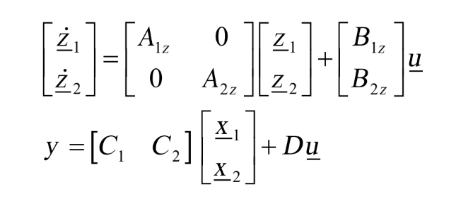

And a whole bunch of steps will lead to:

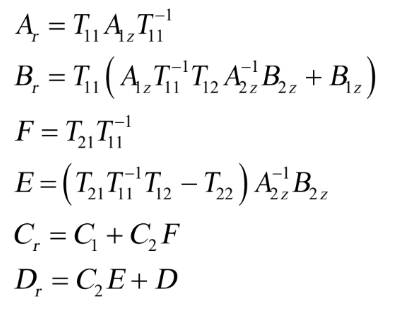

where they all present:

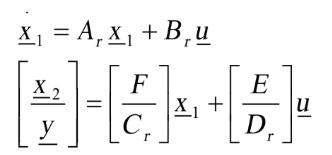

However, in our case, $T_{11}$ is turned out to be SINGULAR, hence noninvertible.

inv(T11)

ans =    Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf
   Inf   Inf   Inf   Inf   Inf   Inf   Inf   Inf


Conclusively, the system is **irriducible** (at least by method 1).

## Model Reduction - Method 2

Following the book instructions to reduce the model using method one "Residuals" provides us with following results.

# Q2-

    **Paper DOI: ****10.4172/2168-9695.1000126**

**Note: First Run the corresponing **`.m`** file to generate all the required variables for this script.**

## System Description

**Longitudinal State Variables:**

- **Longitudinal velocity (u)**: The velocity component along the longitudinal axis of the UAV.

- **Vertical velocity (w)**: The velocity component along the vertical axis of the UAV.

- **Pitch rate (q):** The rate of change of pitch angle of the UAV.

- **Altitude (h):** The altitude or height of the UAV above a reference point.

- **Pitch angle (θ):** The angle between the longitudinal axis of the UAV and the horizontal plane.

**Lateral State Variables:**

- **Lateral velocity (v):** The velocity component along the lateral axis of the UAV.

- **Roll rate (p):** The rate of change of roll angle of the UAV.

- **Yaw angle (ψ):** The angle between the heading direction of the UAV and a reference direction.

- **Yaw rate (r):** The rate of change of yaw angle of the UAV.

- **Bank angle (φ):** The angle between the lateral axis of the UAV and the horizontal plane.

**Longitudinal Input Variables:**

- **Elevator deflection (δe):** The control input that adjusts the pitch angle of the UAV by deflecting the elevator control surface.

- **Thrust control (δt): **The control input that regulates the thrust or engine power of the UAV.

**Lateral Input Variables:**

- **Aileron deflection (δa):** The control input that controls the roll motion of the UAV by deflecting the aileron control surface.

- **Rudder deflection (δr):** The control input that influences the yaw motion of the UAV by deflecting the rudder control surface.

**Longitudinal Output Variables:**

- **Longitudinal velocity (v):** The velocity component along the longitudinal axis of the UAV.

- **Angle of attack (α):** The angle between the relative airflow and the chord line of the UAV's wing.

- **Pitch rate (q):** The rate of change of pitch angle of the UAV.

- **Pitch angle (θ):** The angle between the longitudinal axis of the UAV and the horizontal plane.

- **Altitude (h):** The altitude or height of the UAV above a reference point.

**Lateral Output Variables:**

- **Lateral velocity (v):** The velocity component along the lateral axis of the UAV.

- **Bank angle (φ):** The angle between the lateral axis of the UAV and the horizontal plane.

- **Yaw angle (ψ):** The angle between the heading direction of the UAV and a reference direction.

- **Yaw rate (r):** The rate of change of yaw angle of the UAV.

The state equations of the system can be represented in matrix form as:


$$\dot{x} =Ax+Bu$$


where:

 $\dot{x}$ represents the derivative of the state vector  with respect to time.

$A$ is the state matrix, which describes how the states evolve over time,

 $B$ is the input matrix, which describes how the control inputs affect the system dynamics,

 $u$ represents the control input vector.

In this system:

- **State Matrix (A):**

The matrix  is a 10x10 matrix that defines the dynamics of the UAV system. Each element of this matrix represents the influence of one state on the rate of change of another state. For example, element  represents how state  influences the rate of change of state . In other words, the non-zero elements of this matrix indicate the interdependencies among different states of the system.

- **Input Matrix (B):**

The matrix  is a 10x3 matrix that defines how the control inputs affect the dynamics of the system. Each column corresponds to one control input, and each row corresponds to one state. For example, element  represents how control input  affects the rate of change of state .

The state equations encapsulate the dynamic behavior of the UAV system, describing how the system's states evolve over time in response to control inputs and external influences. These equations are fundamental for understanding and modeling the behavior of the UAV in various flight conditions and for designing control strategies to achieve desired performance objectives.

***Note***: The longitudonal and lateral dynamics of the system are coupled together with the following structure:


$$\textrm{coupled}\;\textrm{dynamics}\cong \left\lbrack \begin{array}{cc}
\textrm{longitudinal}\;\textrm{dynamics} & 0\\
0 & \textrm{lateral}\;\textrm{dynamics}
\end{array}\right\rbrack$$


## Transfer functions and Char Equations

for o=1:numOutputs  
    for i=1:numInputs
        fprintf("Transfer Function for Output_%d/Input_%d}= \n", o,i)
        eval(simplify(G(o,i)))
        fprintf("-------------------------------------------------------------\n")
    end
end

Eigenvalues of matrix `A` are obtained as the following:

eig_A

Thus, the characterisic equation of the open-loop system derives using `det(SI - A)`:

eval(det(s*eye(numStates) - A))

Considering a **Negative Unity Feedback** (**-1** **feedback**) through all of the system states will lead into the following eigenvalues and charactristic equation.

eig_A_prime

And the characteristic equation for the colsed-loop system ( `det(SI - A + BK)` ) :

det(s*eye(numStates) - A_prime)

## How inputs would affect outputs

Based on the obtained transfer functions for the system, the following results are concluded:

The afrementioned results could be observed through `step` responses of the system in the following figure.

step(sys_ss)

open("Q2_UAV.slx")
out = sim("Q2_UAV.slx")

## System Simulation in SimuLink

We could implement the system in Simulink as follows:

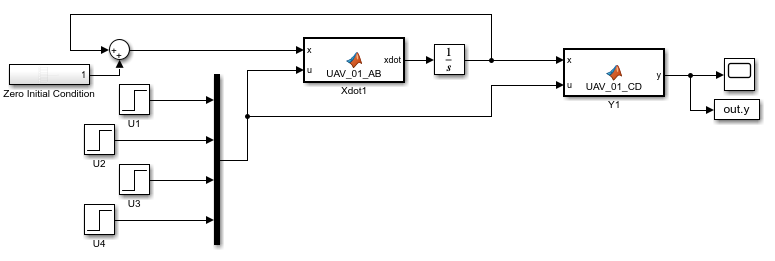

size(out.y.Data)

reshaped = reshape(out.y.Data , [10,size(out.y.Data,3)]);
figure
plot(out.tout, reshaped(1,:), LineWidth=1.5)
hold on
plot(out.tout, reshaped(2,:),LineWidth=1.25)
plot(out.tout, reshaped(3,:),LineWidth=1.5)
plot(out.tout, reshaped(4,:),LineWidth=1.5)
plot(out.tout, reshaped(5,:),LineWidth=1.5)
plot(out.tout, reshaped(6,:),LineWidth=1.5)
plot(out.tout, reshaped(7,:),LineWidth=1.5)
plot(out.tout, reshaped(8,:),LineWidth=1.5)
plot(out.tout, reshaped(9,:),LineWidth=1.5)
plot(out.tout, reshaped(10,:),LineWidth=1.5)
legend("y_1", "y_2", "y_3","y_4","y_5","y_6","y_7","y_8","y_9","y10")

You can run the system under different inputs and initial conditions and study system behaviour.

## Controller Design

Since the eigenvalues of the system include instablity, we may want to desing a controller for the system in order to place its poles where we desire. The required condition for such design is that the Controllability Matrix of the system ( `U=ctrb(A,B)` ) is full rank. 

[rankU , numStates]

According to$10=10$, the system is controllable and its poles can be placed at any desired location. Considering the obtained poles for the system through unity feedback, unity feedback system poles are stable too.

Let's try this out and see if it is able to place system poles where they are stable or not.

step(sys_lqr)

To conclude, we observed that a negative unity feedback can stabilize the system. In addition, we used `lqr` MATALB command to find an optimal `K` for the feedback gain.

## System Type

We know that the Type of a system equals to the number of poles at the origin. So let's recall the system poles which are the eigenvalues of the matrix `A.`

eig_A

Counting poles at the origin:

length(find(eig_A == 0))

So the maximum SystemType of which the system could behave is 1 and since the system is MIMO, Type of the system could vary for different transfer functions of the system due to the zero-pole cancelation throughout system realization.

To study each transfer function (**those that are nonzero**), we need to checkout their denominators.

for o=1:numOutputs  
    for i=1:numInputs
        fprintf("Transfer Function for Output_%d/Input_%d}= \n", o,i)
        eval(simplify(G(o,i)))
        fprintf("-------------------------------------------------------------\n")
    end
end

You can see that the nonzero trasfer funcitons of output_10 are of SystemType 1 and all other nonzero transfer functions are for all other outputs are of System Type 0.

## Singular Values Decomposition

We know that singular values of a matrix `A` are the square roots of the eigenvalues of $A^T A$ or ${\textrm{AA}}^T$. in MATLAB, one could use the command `svd` to obtain these values. Remeber that the correponding decomposition for matrix `A` is as follows:


$$A=\textrm{US}V^T$$


UU
VV
SS

So the singular values of the matrix `A` we have in descending order is:

diag(SS)

## BIBO stability

As mentioned earlier, eigenvalues of the system dynamics matrix `A` show that the system is **Bounded-Input-Bounded_Output**. This is also demonstrated in the section that system is simulated in Simulink if you run the system under various inputs.

## Model Reduction - Method 1

Following the book instructions to reduce the model using method one "Model Separation" provides us with following results.

Az, Bz, Cz

Eigenvalues of matrix `A` had been obtained earlier:

eig_A

We could see that none of the system modes could be assumed as nondominant. The most probable modes to be dropped off the system are $-11\ldotp 6828\pm 10\ldotp 0160$ and -16.0483. So we are expecting to reduce the system from $n=10$ to $q=7$.

According to the following equations, we could separate the system dynamics.

And a whole bunch of steps will lead to:

where they all present:

The following results are obtained:

Ar
Br
Cr
F
E

Hence, the system is reduced from order of 10 to 7 and three nondominant poles are dropped off the system main dynamics.

## Model Reduction - Method 2

Following the book instructions to reduce the model using method one "Residuals" provides us with following results.

Azz
Bzz
Czz

eig_A
eig_Azz

we can see that all the dominant poles of the system are almost preserved and the system is reduced from order of 10 to 7. Note that the system responseness would not be exactly the same.